clear
a = 2.66;
T = .188;
kc = 1.7;

c = tf([a*T,1],[T,1]);

p = tf([0,20],[1,12,20,0]);

p =
 
          20
  -------------------
  s^3 + 12 s^2 + 20 s
 
Continuous-time transfer function.



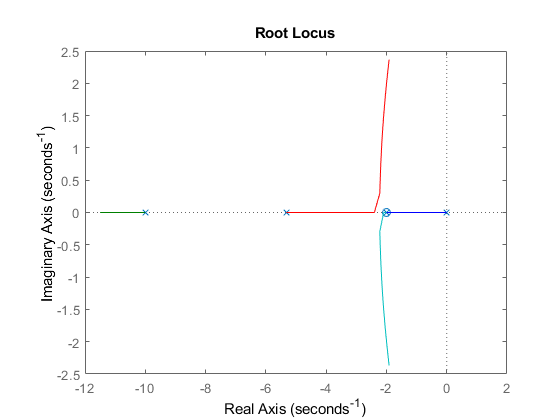

G = c*p;

Kmax=2;
K= 0:Kmax/100:Kmax; % step K by .01
rlocus(G,K);

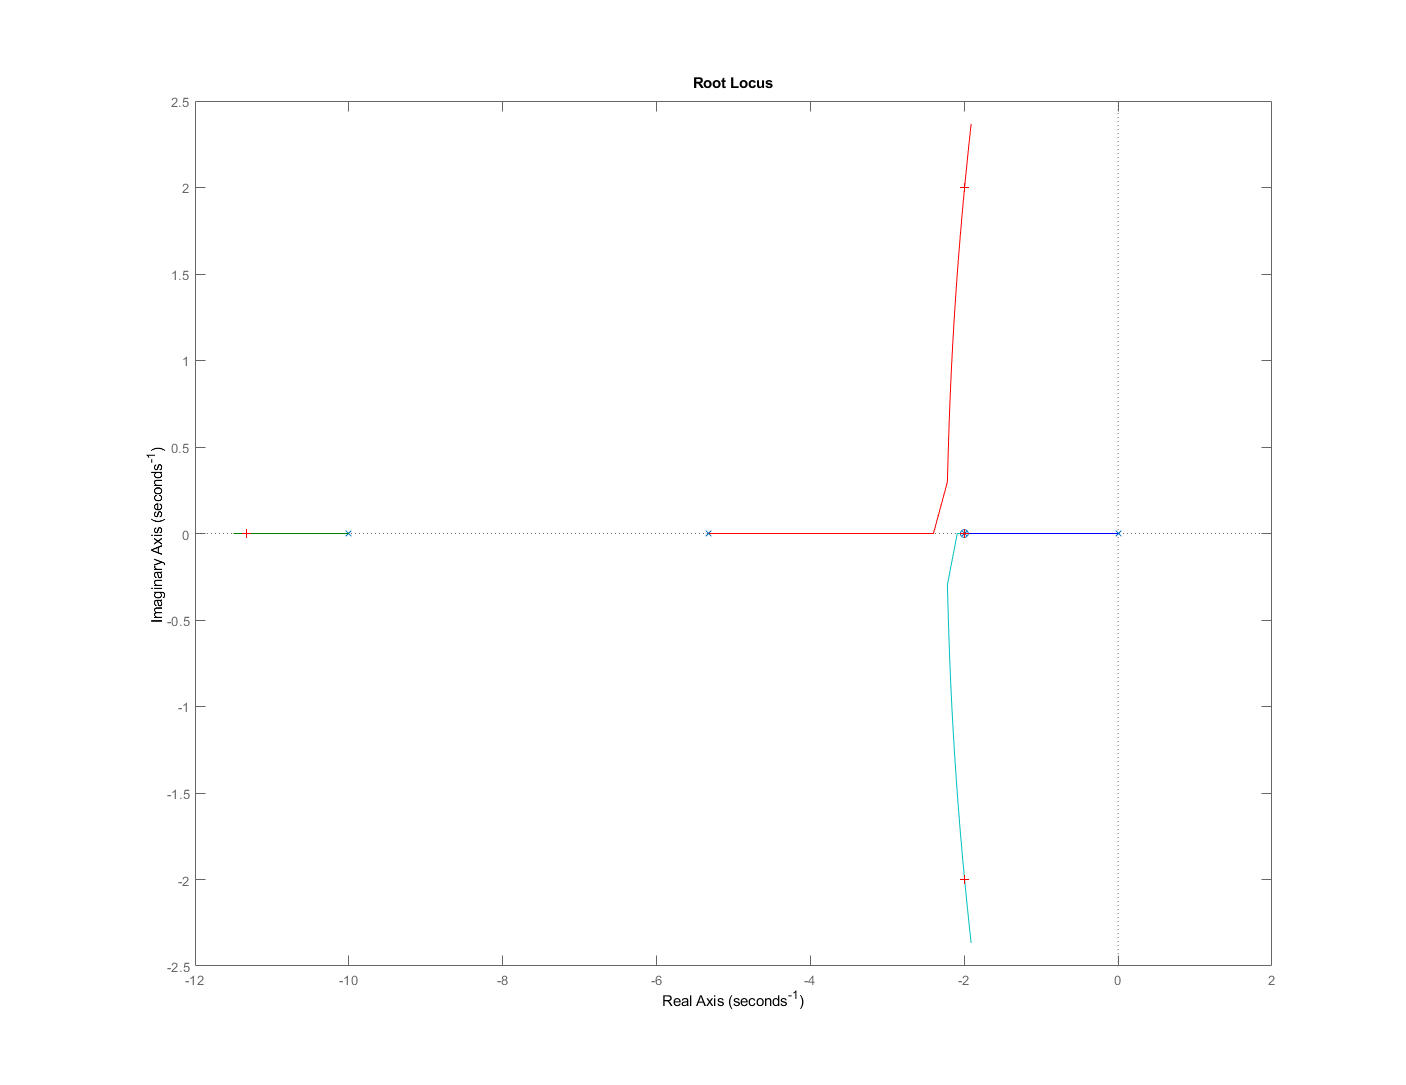

Select a point in the graphics window


selected_point = -1.9972 + 2.0000i

k = 1.6994

rlocusplot(G,K);
[k] = rlocfind(G)